**ECE 572**

**HW4**

**Reza Jahani - Rjahani@ncsu.edu**

**Problem 2.**

A = [1 1 0 0;
     0 0 1 1];
b = [70;
     80];

Aeq = [1 0 1 0;
       0 1 0 1];
beq = [50;
       60];

lb = zeros(4,1);
f = [1 2 3 4];

[x_sta, f_val] = linprog(f,A,b,Aeq,beq,lb);


Optimal solution found.



Aeq = [1 1 0 0 1 0;
       0 0 1 1 0 1;
       1 0 1 0 0 0;
       0 1 0 1 0 0];
beq = [70;
       80;
       50;
       60];

f = [1 2 3 4 1 1];
lb = zeros(6,1);

x = linprog(f,[],[],Aeq,beq,lb);


Optimal solution found.




x = x(1:4);

**Problem 3.**

**Particle Swarm Optimization**

f = @(x) (x(2) - x(1))^4 + 12*x(1)*x(2) - x(1) + x(2) - 3;

d = 10;
N_generation = 20;
x_min = -5;
x_max = 5;

w  = 0.7;
c1 = 2;  
c2 = 2;

x_i = zeros(d,2);
v_i = zeros(d,2);
p_i = zeros(d,2);
f_pbest = zeros(d,1);
for i = 1:d
    x_i(i,:) = x_min + (x_max - x_min) * rand(1, 2); 
    v_i(i,:) = zeros(1, 2);                           
    p_i(i,:) = x_i(i,:);                                
    f_pbest(i) = f(p_i(i,:));                        
end

[f_g, g_idx] = min(f_pbest);
g = p_i(g_idx,:);  
f_gbest = f_g;

best = zeros(N_generation,1);
avg  = zeros(N_generation,1);
worst = zeros(N_generation,1);


for k = 1:N_generation
    
    for i = 1:d
        r_i = rand(1,2);
        s_i = rand(1,2);
        
        v_i(i,:) = w*v_i(i,:) + c1*r_i.*(p_i(i,:)-x_i(i,:)) + c2*s_i.*(g - x_i(i,:));
        x_i(i,:) = x_i(i,:) + v_i(i,:);
        
        % Boundary check
        x_i(i,:) = max(min(x_i(i,:), x_max), x_min);
    end
    
   
    for i = 1:d
        f_current = f(x_i(i,:));
        if f_current < f(p_i(i,:))
            p_i(i,:) = x_i(i,:);
            f_pbest(i) = f_current;
        end
    end
    
    [f_min, idx] = min(f_pbest);
    if f_min < f_g
        g = p_i(idx,:);
        f_g = f_min;
    end
    

    all_f = zeros(d,1);
    for i = 1:d
        all_f(i) = f(x_i(i,:));
    end
    best(k) = min(all_f);
    avg(k)  = mean(all_f);
    worst(k)= max(all_f);
    
    fprintf('Gen %3d: f* = %.6f at [%.4f, %.4f]\n', k, f_gbest, g(1), g(2));
end

Gen   1: f* = 3.485241 at [-0.2392, -0.4256]
Gen   2: f* = 3.485241 at [0.3392, -0.7849]
Gen   3: f* = 3.485241 at [0.3392, -0.7849]
Gen   4: f* = 3.485241 at [0.3392, -0.7849]
Gen   5: f* = 3.485241 at [0.3392, -0.7849]
Gen   6: f* = 3.485241 at [0.3392, -0.7849]
Gen   7: f* = 3.485241 at [0.5900, -0.6731]
Gen   8: f* = 3.485241 at [0.5900, -0.6731]
Gen   9: f* = 3.485241 at [0.5900, -0.6731]
Gen  10: f* = 3.485241 at [0.5900, -0.6731]
Gen  11: f* = 3.485241 at [0.5900, -0.6731]
Gen  12: f* = 3.485241 at [0.5900, -0.6731]
Gen  13: f* = 3.485241 at [0.5900, -0.6731]
Gen  14: f* = 3.485241 at [0.6332, -0.6457]
Gen  15: f* = 3.485241 at [0.6332, -0.6457]
Gen  16: f* = 3.485241 at [0.6332, -0.6457]
Gen  17: f* = 3.485241 at [0.6332, -0.6457]
Gen  18: f* = 3.485241 at [0.6332, -0.6457]
Gen  19: f* = 3.485241 at [0.6332, -0.6457]
Gen  20: f* = 3.485241 at [0.6332, -0.6457]



fprintf('x1 = %.4f, x2 = %.4f, f(x1,x2) = %.6f\n', g(1), g(2), f_gbest);

x1 = 0.6332, x2 = -0.6457, f(x1,x2) = 3.485241


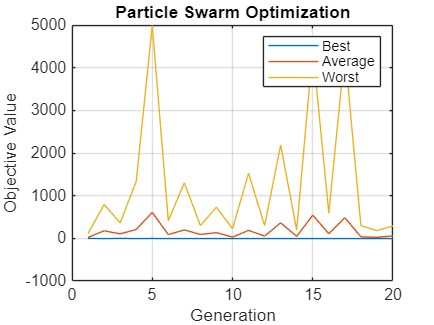


figure;
plot(best); hold on;
plot(avg);
plot(worst);
xlabel('Generation');
ylabel('Objective Value');
legend('Best','Average','Worst');
title('Particle Swarm Optimization');
grid on;

**Canonical Genetic Algorithm**

f = @(x1,x2) (x2-x1).^4 + 12*x1*x2 - x1 + x2 - 3;

fitness = @(x1,x2) 1 ./ (1 + f(x1,x2) - min([-10, f(x1,x2)]));  

N_population = 1000;
N_generation = 10;
x_min = -5;
x_max = 5;
n_bits = 16;
Pc = 0.75;
Pm = 0.01;

x_pop = x_min + (x_max - x_min)*rand(N_population,2);

best = zeros(N_generation,1);
avg  = zeros(N_generation,1);
worst = zeros(N_generation,1);

for n = 1:N_generation
    
    %% Selection
    fitness_vals = zeros(N_population,1);
    for i = 1:N_population
        xi = x_pop(i,:);
        fitness_vals(i) = fitness(xi(1), xi(2));
    end

    [~,I] = maxk(fitness_vals, N_population/2);     
    M_k = x_pop(I,:);


    %% Cross-over / Mutation
    C_k = zeros(2*size(M_k,1), 2);

    for i = 1:size(M_k,1)
        p_1 = M_k(i,:);
        idx = randi(size(M_k,1));
        while idx == i
            idx = randi(size(M_k,1));
        end
        p_2 = M_k(idx,:);

        p1_x1_bin = code(p_1(1), n_bits, x_min, x_max);
        p1_x2_bin = code(p_1(2), n_bits, x_min, x_max);
        p2_x1_bin = code(p_2(1), n_bits, x_min, x_max);
        p2_x2_bin = code(p_2(2), n_bits, x_min, x_max);

        
        if rand < Pc
            xover = randi(n_bits-1);
            ch1_x1_bin = [p1_x1_bin(1:xover) p2_x1_bin(xover+1:end)];
            ch1_x2_bin = [p1_x2_bin(1:xover) p2_x2_bin(xover+1:end)];
            ch2_x1_bin = [p2_x1_bin(1:xover) p1_x1_bin(xover+1:end)];
            ch2_x2_bin = [p2_x2_bin(1:xover) p1_x2_bin(xover+1:end)];
        else
            ch1_x1_bin = p1_x1_bin;
            ch1_x2_bin = p1_x2_bin;
            ch2_x1_bin = p2_x1_bin;
            ch2_x2_bin = p2_x2_bin;
        end

        if rand < Pm
            ch1_x1_bin = mutation(ch1_x1_bin);
        end
        if rand < Pm
            ch1_x2_bin = mutation(ch1_x2_bin);
        end
        if rand < Pm
            ch2_x1_bin = mutation(ch2_x1_bin);
        end
        if rand < Pm
            ch2_x2_bin = mutation(ch2_x2_bin);
        end

        ch1 = [decode(ch1_x1_bin, n_bits, x_min, x_max) decode(ch1_x2_bin, n_bits, x_min, x_max)];
        ch2 = [decode(ch2_x1_bin, n_bits, x_min, x_max) decode(ch2_x2_bin, n_bits, x_min, x_max)];

        C_k(2*i-1,:) = ch1;
        C_k(2*i,:)   = ch2;
    end

    %% New Population
    x_pop = C_k;
    N_population = size(x_pop,1);

    
    all_f = zeros(N_population,1);
    for i = 1:N_population
        all_f(i) = f(x_pop(i,1), x_pop(i,2));
    end

    best(n) = min(all_f);
    avg(n)  = mean(all_f);
    worst(n)= max(all_f);

end


x_star = x_pop(1,:);
fprintf('x1 = %.2f, x2 = %.2f, f(x1,x2) = %.3f\n', ...
        x_star(1), x_star(2), f(x_star(1), x_star(2)));

x1 = 0.65, x2 = -0.64, f(x1,x2) = -6.513


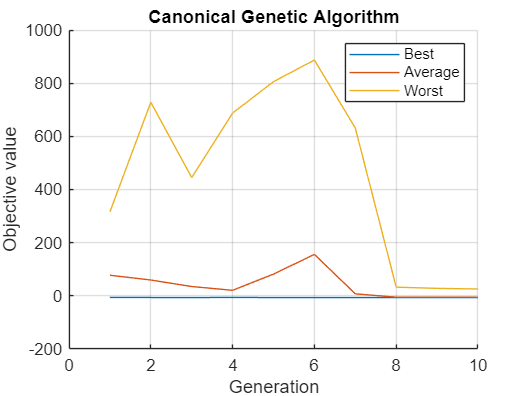


figure; hold on;
plot(best);
plot(avg);
plot(worst/10);
% ylim([-10,2000]);
xlabel('Generation');
ylabel('Objective value');
legend('Best','Average','Worst');
title('Canonical Genetic Algorithm');
grid on;



function x_genotype = code(x, n_bits, x_min, x_max)
    x_int = round((2^n_bits - 1)* (x - x_min)/(x_max - x_min));
    x_int = max(min(x_int, 2^n_bits-1), 0);
    x_genotype = dec2bin(x_int, n_bits);
end

function x_phenotype = decode(x_genotype, n_bits, x_min, x_max)
    x_int = bin2dec(x_genotype);
    x_phenotype = x_min + x_int*((x_max-x_min)/(2^n_bits - 1));
end

function y = mutation(x)
    y = x;
    idx = randi(length(x));
    if x(idx) == '0'
        y(idx) = '1';
    else
        y(idx) = '0';
    end
end

**Problem 5**

f = [0 0 0 0 4 3 3 2 2];

A_T = [
     1  -1  0  0   1  0  0  0  0;
    -1   1  0  0   0  1  0  0  0;
    -1   1  1 -1   0  0  1  0  0; 
     0   0 -1  1   0  0  0  1  0;
     0   0 -1  1   0  0  0  0  1]; 

c = [0; 10; 0; 6; 20];

A_inq = - A_T;
b_inq = -c;
lb = zeros(9,1);

[y_opt,val_opt] = linprog(f, A_inq, b_inq, [], [], lb, []);


Optimal solution found.



% Checking for constraints status

constraint_val = A_T * y_opt;

eq_c = constraint_val == c;
ineq_c = constraint_val > c;

